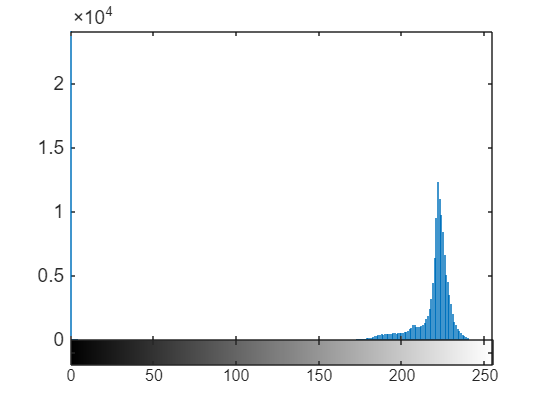

conc1 = imread("conc1.jpg");
conc2 = imread("conc2.jpg");
conc3 = imread("conc3.jpg");
conc4 = imread("conc4.jpg");
conc5 = imread("conc5.jpg");
conc6 = imread("conc6.jpg");
conc7 = imread("conc7.jpg");

%figure
%montage({conc1,conc2,conc3,conc4,conc5,conc6,conc7})
%title("Imagem sem tratamento")

conc_output1 = imread("conc1_output.jpg");
conc_output2 = imread("conc2_output.jpg");
conc_output3 = imread("conc3_output.jpg");
conc_output4 = imread("conc4_output.jpg");
conc_output5 = imread("conc5_output.jpg");
conc_output6 = imread("conc6_output.jpg");
conc_output7 = imread("conc7_output.jpg");

%montage({conc_output1,conc_output2,conc_output3,conc_output4,conc_output5,conc_output6,conc_output7})
%title("Máscara a ser aplicada")

brancoB1 = conc1(:,:,3);
brancoB2 = conc2(:,:,3);
brancoB3 = conc3(:,:,3);
brancoB4 = conc4(:,:,3);
brancoB5 = conc5(:,:,3);
brancoB6 = conc6(:,:,3);
brancoB7 = conc7(:,:,3);

%montage({brancoB1,brancoB2,brancoB3,brancoB4,brancoB5,brancoB6,brancoB7})
%title("Decompondo a imagem apenas para o vetor azul")

brancosub1 = imsubtract(brancoB1,conc_output1);
brancosub2 = imsubtract(brancoB2,conc_output2);
brancosub3 = imsubtract(brancoB3,conc_output3);
brancosub4 = imsubtract(brancoB4,conc_output4);
brancosub5 = imsubtract(brancoB5,conc_output5);
brancosub6 = imsubtract(brancoB6,conc_output6);
brancosub7 = imsubtract(brancoB7,conc_output7);
%montage({brancosub1,brancosub2,brancosub3,brancosub4,brancosub5,brancosub6,brancosub7})
%title("Aplicando a máscara no vetor azul")

imhist(brancosub1);

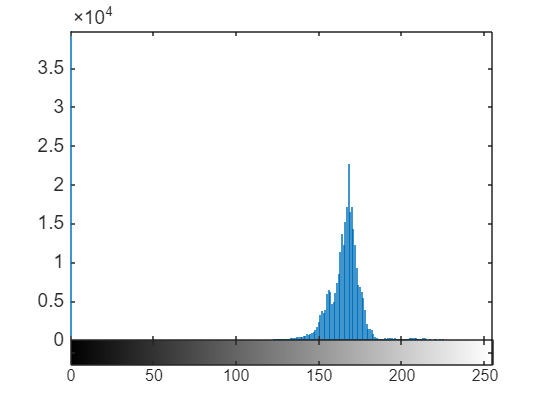

imhist(brancosub2);

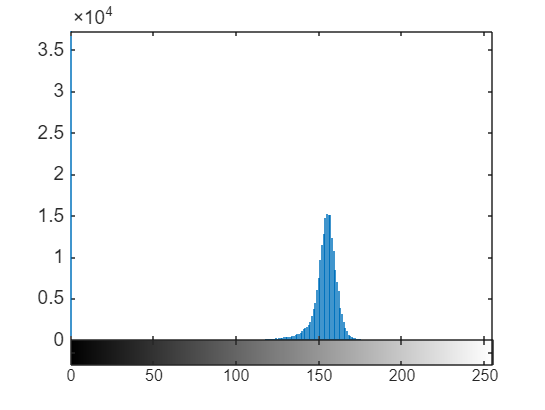

imhist(brancosub3);

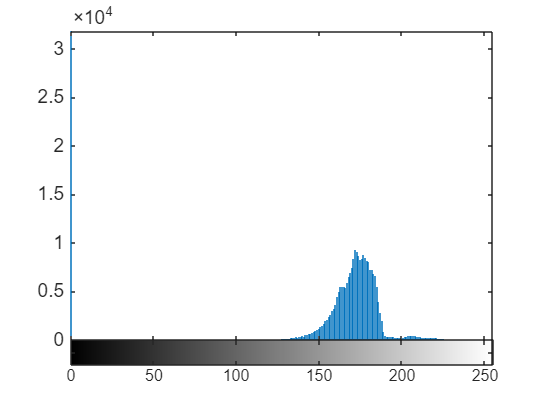

imhist(brancosub4);

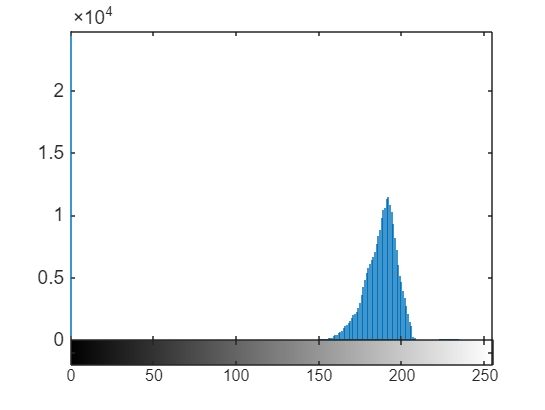

imhist(brancosub5);

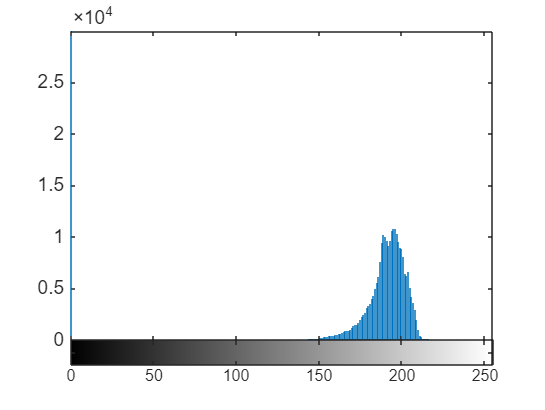

imhist(brancosub6);

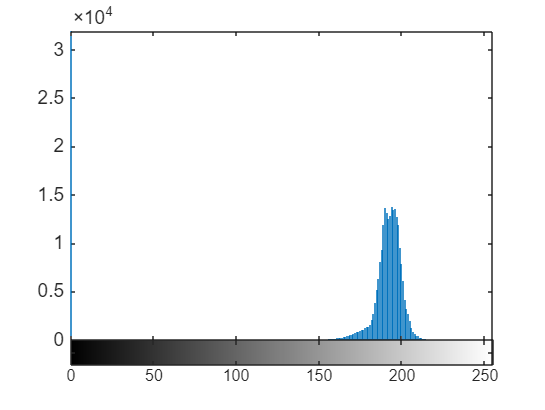

imhist(brancosub7);


X1 = imhist(brancosub1);
X2 = imhist(brancosub2);
X3 = imhist(brancosub3);
X4 = imhist(brancosub4);
X5 = imhist(brancosub5);
X6 = imhist(brancosub6);
X7 = imhist(brancosub7);

X1(1, :) = zeros(1, 1);
X2(1, :) = zeros(1, 1);
X3(1, :) = zeros(1, 1);
X4(1, :) = zeros(1, 1);
X5(1, :) = zeros(1, 1);
X6(1, :) = zeros(1, 1);
X7(1, :) = zeros(1, 1);

rgb1 = 255-(find(X1==max(X1)) - 1);
rgb2 = 255-(find(X2==max(X2)) - 1);
rgb3 = 255-(find(X3==max(X3)) - 1);
rgb4 = 255-(find(X4==max(X4)) - 1);
rgb5 = 255-(find(X5==max(X5)) - 1);
rgb6 = 255-(find(X6==max(X6)) - 1);
rgb7 = 255-(find(X7==max(X7)) - 1);

rgb2_corrigido = rgb2 - rgb1;
rgb3_corrigido = rgb3 - rgb1;
rgb4_corrigido = rgb4 - rgb1;
rgb5_corrigido = rgb5 - rgb1;
rgb6_corrigido = rgb6 - rgb1;
rgb7_corrigido = rgb7 - rgb1;

c1 = 0

c1 = 0

c2 = 25.0

c2 = 25

c3 = 20.0

c3 = 20

c4 = 15.0

c4 = 15

c5 = 10.0

c5 = 10

c6 = 5.0

c6 = 5

c7 = 2.5

c7 = 2.5000


A = [c1 rgb1;c2 rgb2;c3 rgb3;c4 rgb4;c5 rgb5;c6 rgb6;c7 rgb7]

A =          0   33.0000
   25.0000   87.0000
   20.0000  100.0000
   15.0000   83.0000
   10.0000   63.0000
    5.0000   60.0000
    2.5000   61.0000



%x = [c2 c3 c4 c5 c6 c7];
%y = [rgb2_corrigido rgb3_corrigido rgb4_corrigido rgb5_corrigido rgb6_corrigido rgb7_corrigido];
%plot(fitlm(x,y))
%ylabel("Sinal Analítico", "Interpreter", "none", "FontName", "Helvetica", "FontAngle", "normal", "FontWeight", "normal")
%title("Curva Analítica", "Interpreter", "none")
%xlabel("Concentração (mg/L)", "Interpreter", "none", "FontName", "Helvetica", "FontAngle", "normal", "FontWeight", "normal")
